# Plot figure 4

## Load data

addpath(genpath('../public_code'))

## Make some code that plot the same thing for each set of before / after drug

nstrain_s2_set = {'male_before_timp_180511', ...
               'male_after_timp_180526', ...
               'female_before_timp_180413', ...
               'female_after_timp_180430', ...
               'male_before_bsa_200713' , ...
               'male_after_bsa_200727' };

nstrain_subn_set = {'male_before_timp_180511', ...
               'male_after_timp_180526', ...
               'female_before_timp_180413_sub13mice', ...
               'female_after_timp_180430_sub13mice', ...
               'male_before_bsa_200713_sub9mice' , ...
               'male_after_bsa_200727_sub9mice' };



%%
jij2_alldata = {};
hir2_alldata = {};


didf2 = [0, 4; 5, 9];
count = 0;
for i = 1:6
    nstrain = nstrain_s2_set{i};
    nstrain_subn = nstrain_subn_set{i};
    for j = 1:2
        disp(['i = ' num2str(i) ', j = ' num2str(j)])
        count = count + 1; 
        di = didf2(j,1);
        df = didf2(j,2);

        sub_flag = 1;

%         fp = ['sme_pairwise_l2_' nstrain_subn '_di' num2str(di) ...
%             '_df' num2str(df) '_' ttscheme '_beta0.mat'];


        fp = ['sme_pairwise_l2_' nstrain_subn '_di' num2str(di) ...
            '_df' num2str(df) '_bshalf.mat'];

        load(fp,'jijFinal3_nbs','hirFinal3_nbs');

        jij2_alldata{count} = jijFinal3_nbs;
        hir2_alldata{count} = hirFinal3_nbs;

    end
end



## Select cohort: M1, M4, or F1


nNodes2 = [15, 13, 9];
nEdges2 = nNodes2.*(nNodes2-1)/2;
nStates = 4;

% cohort_name = 'male_timp';
% cohort_name = 'female_timp';
cohort_name = 'male_bsa';

if strcmp(cohort_name, 'male_timp')
    count_start = 0;
    nEdges = nEdges2(1);
    nNodes = nNodes2(1);
    drug_name = 'TIMP';
    nstrain_title = 'M1 - male/TIMP';
    fig_name_part = 'm1_timp'; %'frustration_5day_m1_timp.svg';
elseif strcmp(cohort_name, 'female_timp')
    count_start = 4;
    nEdges = nEdges2(2);
    nNodes = nNodes2(2);
    drug_name = 'TIMP';
    nstrain_title = 'F1 - female/TIMP';
    fig_name_part = 'f1_timp'; %'frustration_5day_f1_timp.svg';
elseif strcmp(cohort_name, 'male_bsa')
    count_start = 8;
    nEdges = nEdges2(3);
    nNodes = nNodes2(3);
    drug_name = 'BSA';
    nstrain_title = 'M4 - male/BSA';
    fig_name_part = 'm4_bsa'; %'frustration_5day_m4_bsa.svg';
end

jij2_5day4 = [];
jij2_flat = [];

frus_master = [];

for i = 1:4
    jij2_5day4 = [jij2_5day4 jij2_alldata{count_start+i}];
    jij2_flat = [jij2_flat jij2_alldata{count_start+i}'];

    frus_master = [frus_master ...
         compute_frustration_bs(jij2_alldata{count_start+i}, ...
         nNodes)'] ;

end

pMat = nan(4);
for idata = 1:3
    for jdata = idata+1:4
        pMat(idata,jdata) = ...
            welch_ttest_randomhalves(frus_master(:,idata), frus_master(:,jdata));
    end
end
disp(pMat)


## Figure 4B: compute and plot global dissatisfaction triplet index for cohort M1, F1, M4

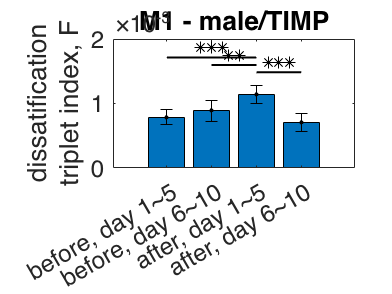



ntest = 6;
sigMat = (pMat < 0.025/ntest) + (pMat < 0.01/2/ntest) + (pMat < 0.001/2/ntest);

% make plots
figure()
bar(mean(frus_master))
hold on
errorbar(mean(frus_master), std(frus_master)/sqrt(2),'k.')
hold off
xticks([1,2,3,4])
xticklabels({'before, day 1~5',...
    'before, day 6~10',...
    'after, day 1~5',...
    'after, day 6~10'})
set(gca,'fontsize',12)
% ylabel('frustration, F')
ylabel({'dissatification'; 'triplet index, F'})

title(nstrain_title)
hold on

edgeList = [1,2; 3,4; 2,3; 1,3; 2,4; 1,4];

count = 1;
for iedge = 1:6
    my_edge = edgeList(iedge,:);
    i = my_edge(1);
    j = my_edge(2);

    if (i == 1 && j == 3) || (i == 2 && j == 3) || (i == 3 && j == 4)
%     if sigMat(i,j) > 0
%         plot([i,j], [1 1]*max(mean(frus_master))*(1.15 + 0.06*count), '-k', 'LineWidth',1)
        plot([i,j], ...
             [1 1]*max(mean(frus_master))...
                    *(1.2 + 0.1*count), '-k', 'LineWidth',1)
        if sigMat(i,j) == 1
            plot((i+j)/2, max(mean(frus_master))*(1.2 + 0.1*count)+0.00015,...
                '*k')
        elseif sigMat(i,j) == 2
            plot((i+j)/2+[-0.12, 0.12], [1,1]*max(mean(frus_master))*(1.2 + 0.1*count)+0.00015,...
                '*k')
        elseif sigMat(i,j) == 3
            plot((i+j)/2+[-0.24, 0, 0.24], [1,1,1]*max(mean(frus_master))*(1.2 + 0.1*count)+0.00015,...
                '*k')
        else
            text((i+j)/2, max(mean(frus_master))*(1.2 + 0.1*count)+0.00015,...
                'n.s.')
        end
        count = count + 1;
    end
end

hold off

set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 3, 3]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [3, 3]);  
% % print(gcf, 'cll_5day_m1_v2.pdf', '-dpdf');
% print(gcf, 'jij_5day_m1_timp.svg', '-dsvg');
% print(gcf, 'jij_5day_f1_timp.svg', '-dsvg');
print(gcf, ['frustration_5day_' fig_name_part '.svg'], '-dsvg');


% fig_name_part = 'm1_timp';

## Figure 4 -- figure supplement 1: compute global dissatisfaction triplet index (F) using subgroups of mice (N_sub = 9) from cohort M1 and F1, such that the results can be compared to that of the cohort M4 (N = 9). The pairwise interactions are learned using the original group size. Subgrouping is performed at the level of the learned interaction. 

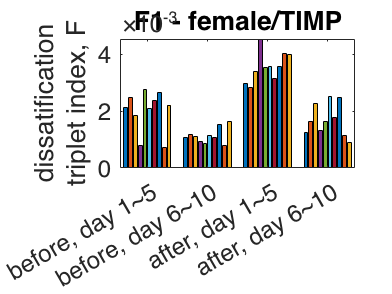


nNodes2 = [15, 13, 9];
nEdges2 = nNodes2.*(nNodes2-1)/2;
nStates = 4;

load sub9_index.mat

% cohort_name = 'male_timp';
cohort_name = 'female_timp';
% cohort_name = 'male_bsa';

if strcmp(cohort_name, 'male_timp')
    count_start = 0;
    nEdges = nEdges2(1);
    nNodes = nNodes2(1);
    drug_name = 'TIMP';
    nstrain_title = 'M1 - male/TIMP';
    fig_name_part = 'm1_timp'; %'frustration_5day_m1_timp.svg';
    sub9_idx = m1_sub9_idx;
elseif strcmp(cohort_name, 'female_timp')
    count_start = 4;
    nEdges = nEdges2(2);
    nNodes = nNodes2(2);
    drug_name = 'TIMP';
    nstrain_title = 'F1 - female/TIMP';
    fig_name_part = 'f1_timp'; %'frustration_5day_f1_timp.svg';
    sub9_idx = f1_sub9_idx;
elseif strcmp(cohort_name, 'male_bsa')
    count_start = 8;
    nEdges = nEdges2(3);
    nNodes = nNodes2(3);
    drug_name = 'BSA';
    nstrain_title = 'M4 - male/BSA';
    fig_name_part = 'm4_bsa'; %'frustration_5day_m4_bsa.svg';
end
%%

jij2_sub9_5day4 = [];
jij2_sub9_flat = [];

% frus_sub9_master = [];

nsubsample = 10;
frus_sub9_master = zeros(10,4,nsubsample);

for isubsample = 1:nsubsample
%     sub9_idx = randperm(nNodes, 9);
%%
    out_idx = setdiff(1:nNodes, sub9_idx(isubsample,:));
    connectivityMat = ones(nNodes);
    connectivityMat(out_idx,:) = 0;
    connectivityMat(:, out_idx) = 0;
    connectivity_flat = makeUpt(connectivityMat);
    connectivity_flat = (connectivity_flat>0.5) ; % turn double into logical values
    
%     nNodes = 9;
    for i = 1:4
        jij2_sub9_5day4 = [jij2_sub9_5day4 jij2_alldata{count_start+i}(connectivity_flat,:)];
%         jij2_sub9_flat = [jij2_sub9_flat jij2_alldata{count_start+i}(connectivity_flat,:)'];
    
    
        frus_sub9_master(:,i,isubsample) = ...
             compute_frustration_bs(...
             jij2_alldata{count_start+i}(connectivity_flat,:), ...
             9) ;
    
    end
end

figure()
% the last one is on subsample... so we should actually average the ibs
% first, since that's on sub data (time)
bar(squeeze(mean(frus_sub9_master,1)))
% hold on
% errorbar(nanmean(frus_sub9_master), nanstd(frus_sub9_master)/sqrt(2),'k.')
% hold off
xticks([1,2,3,4])
xticklabels({'before, day 1~5',...
    'before, day 6~10',...
    'after, day 1~5',...
    'after, day 6~10'})
set(gca,'fontsize',12)
% ylabel('frustration, F')
ylabel({'dissatification'; 'triplet index, F'})
title(nstrain_title)


set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 3, 3]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [3, 3]);  
print(gcf, ['frustration_5day_10sub9_' fig_name_part '.svg'], '-dsvg');

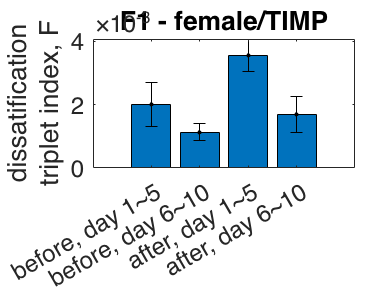


figure()
bar(mean(mean(frus_sub9_master,1),3))
hold on
errorbar(mean(mean(frus_sub9_master,1),3), ...
    std(mean(frus_sub9_master,1),0,3),'k.')
hold off
xticks([1,2,3,4])
xticklabels({'before, day 1~5',...
    'before, day 6~10',...
    'after, day 1~5',...
    'after, day 6~10'})
title(nstrain_title)
set(gca,'fontsize',12)
ylabel({'dissatification'; 'triplet index, F'})
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 3, 3]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [3, 3]);  
print(gcf, ['frustration_5day_avg10sub9_' fig_name_part '.svg'], '-dsvg');

## Figure 4 -- figure supplement 2: compute global dissatisfaction triplet index (F) using interactions learned from subgroups of mice (N_sub = 9) from cohort M1 and F1, such that the results can be compared to that of the cohort M4 (N = 9).

cohort_name = 'female_timp';
nNodes = 9;

jij2_alldata_sub9learn = {};

didf2 = [0, 4; 5, 9];
count = 0;
for i = 1:4
    nstrain = nstrain_s2_set{i};
    nstrain_subn = nstrain_subn_set{i};
    for j = 1:2
        disp(['i = ' num2str(i) ', j = ' num2str(j)])
        count = count + 1; 
        di = didf2(j,1);
        df = didf2(j,2);

        sub_flag = 1;

%         fp = ['sme_pairwise_l2_' nstrain_subn '_di' num2str(di) ...
%             '_df' num2str(df) '_' ttscheme '_beta0.mat'];


        fp = ['sme_pairwise_l2_' nstrain ...
             '_sub9mice_di' num2str(di) ...
             '_df' num2str(df) '_bshalf_sub9.mat'];

%         fp = ['sme_pairwise_l2_' nstrain_subn '_di' num2str(di) ...
%             '_df' num2str(df) '_bshalf.mat'];

        load(fp,'jijFinal3_nbs_sub9');

        jij2_alldata_sub9learn{count} = jijFinal3_nbs_sub9;
%         jijFinal3_nbs_sub9(:, ibs, isubsample) 
    end
end

i = 1, j = 1
i = 1, j = 2
i = 2, j = 1
i = 2, j = 2
i = 3, j = 1
i = 3, j = 2
i = 4, j = 1
i = 4, j = 2


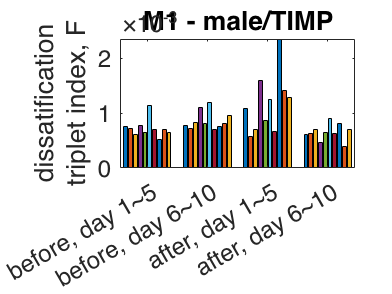



load sub9_index.mat

cohort_name = 'male_timp';
% cohort_name = 'female_timp';
% cohort_name = 'male_bsa';

nNodes = 9;
nEdges = 36;
nsubsample = 10;
frus_sub9learn_master = zeros(10,4,nsubsample);


if strcmp(cohort_name, 'male_timp')
    count_start = 0;
    drug_name = 'TIMP';
    nstrain_title = 'M1 - male/TIMP';
    fig_name_part = 'm1_timp'; %'frustration_5day_m1_timp.svg';
elseif strcmp(cohort_name, 'female_timp')
    count_start = 4;
    drug_name = 'TIMP';
    nstrain_title = 'F1 - female/TIMP';
    fig_name_part = 'f1_timp'; %'frustration_5day_f1_timp.svg';
end

for isubsample = 1:10
    for i = 1:4
        frus_sub9learn_master(:,i,isubsample) = ...
             compute_frustration_bs(...
             jij2_alldata_sub9learn{count_start+i}(:,:,isubsample), ...
             nNodes) ;
    end
end


figure()
% the last one is on subsample... so we should actually average the ibs
% first, since that's on sub data (time)
bar(squeeze(mean(frus_sub9learn_master,1)))
% hold on
% errorbar(nanmean(frus_sub9_master), nanstd(frus_sub9_master)/sqrt(2),'k.')
% hold off
xticks([1,2,3,4])
xticklabels({'before, day 1~5',...
    'before, day 6~10',...
    'after, day 1~5',...
    'after, day 6~10'})
set(gca,'fontsize',12)
% ylabel('frustration, F')
ylabel({'dissatification'; 'triplet index, F'})
title(nstrain_title)


set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 3, 3]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [3, 3]);  
print(gcf, ['frustration_5day_10sub9learn_' fig_name_part '.svg'], '-dsvg');

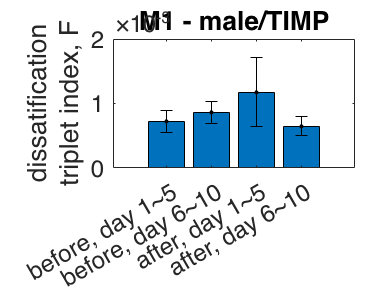


figure()
bar(mean(mean(frus_sub9learn_master,1),3))
hold on
errorbar(mean(mean(frus_sub9learn_master,1),3), ...
    std(mean(frus_sub9learn_master,1),0,3),'k.')
hold off
xticks([1,2,3,4])
xticklabels({'before, day 1~5',...
    'before, day 6~10',...
    'after, day 1~5',...
    'after, day 6~10'})
title(nstrain_title)
set(gca,'fontsize',12)
ylabel({'dissatification'; 'triplet index, F'})
set(gcf, 'PaperUnits', 'inches');
set(gcf, 'PaperPosition', [0, 0, 3, 3]);  % 6 inches wide, 4 inches tall
set(gcf, 'PaperSize', [3, 3]);  
print(gcf, ['frustration_5day_avg10sub9learn_' fig_name_part '.svg'], '-dsvg');

## How we generated sub9_index.mat: Fix the index of subgroups from male TIMP and female TIMP

rng(5)
f1_sub9_idx = zeros(10, 9);
for i = 1:10
    f1_sub9_idx(i,:) = randperm(13, 9);
end

m1_sub9_idx = zeros(10, 9);
for i = 1:10
    m1_sub9_idx(i,:) = randperm(15, 9);
end

save('sub9_index.mat', 'f1_sub9_idx', 'm1_sub9_idx');

## Figure 4 - supplementary figure 3: frustration vs. shuffled frustration

[~, frus_f5bt_bs_shuffle] = compute_shuffled_frustration_bs(jij_f5bt, nNodes);
[~, frus_l5bt_bs_shuffle] = compute_shuffled_frustration_bs(jij_l5bt, nNodes);
[~, frus_f5at_bs_shuffle] = compute_shuffled_frustration_bs(jij_f5at, nNodes);
[~, frus_l5at_bs_shuffle] = compute_shuffled_frustration_bs(jij_l5at, nNodes);


frus_shuffle_master3 = cat(3, frus_f5bt_bs_shuffle,...
    frus_l5bt_bs_shuffle,  frus_f5at_bs_shuffle, ...
    frus_l5at_bs_shuffle);


figure()
for idata = 1:4
    subplot(2,2,idata)
    errorbar(frus_master(:,idata), ...
        mean(frus_shuffle_master3(:,:,idata)), ...
        std(frus_shuffle_master3(:,:,idata)), '.');
    hold on
    plot([0 1],[0 1],'-')
     axis([0 1.1 0 1.1]*max(max(frus_master(:)), ...
        max(max(mean(frus_shuffle_master3) + ...
        std(frus_shuffle_master3)))));
    hold off
    axis square
    set(gca,'fontsize',12)
    ylabel('F_{shuffled}')
    xlabel('F_{random half}')

end

%
subplot(2,2,1)
xlabel('')
xticklabels('')

subplot(2,2,2)
ylabel('')
xlabel('')
xticklabels('')
yticklabels('')

subplot(2,2,4)
ylabel('')
yticklabels('')



function [frus_bs] = compute_frustration_bs(jij2, nNodes)

nbs = size(jij2,2);
frus_bs = nan(1, nbs);
for ibs = 1:nbs
    %%
    my_jij = jij2(:,ibs);
    my_jijMat = recoverUpt(my_jij, nNodes);
    %%
    frus2 = compute_frustration_from_jijmat(my_jijMat);
    if ~isempty(frus2(1,frus2(2,:)==2))
        my_frus = -mean(frus2(1,frus2(2,:)==2));
    else
        my_frus = 0;
    end
    frus_bs(ibs) = my_frus;
end

end


function [nstrain_before, nstrain_after, nstrain_title, nNodes] = load_data_figure4(nstrain)


switch nstrain
    case 'male_timp'
        nstrain_before = 'male_before_timp_180511';
        nstrain_after = 'male_after_timp_180526'; nNodes = 15;
        nstrain_title = 'M1 - male/TIMP';
    case 'male_bsa'
        nstrain_before = 'male_before_bsa_200713'; 
        nstrain_after = 'male_after_bsa_200727'; nNodes = 9 ; %10;
        nstrain_title = 'M4 - male/BSA';
    case 'female_timp'
        nstrain_before = 'female_before_timp_180413';
%         nstrain_after = 'female_after_timp_180430_nomouse13'; 

        nstrain_after = 'female_after_timp_180430'; 
        nNodes = 13; % after removing mouse 13, nNodes becomes 13, was 14
        nstrain_title = 'F1 - female/TIMP';
    otherwise
        error('Wrong strain name. Choose between male_timp, male_bsa, or female_timp.')
end

disp(['nNodes = ' num2str(nNodes)])


end

function [jij2, hir2] = load_sme_params_5days(nstrain, n5days, nNodes, method)
%n5days = 'first' or 'last'

%%
nStates = 4;

tp = '~/MyDocuments/physics/projects/social_mice/output/';

nbs = 10;
jij2 = nan(nNodes*(nNodes-1)/2, nbs);
hir2 = nan(nNodes*(nStates-1), nbs);


for ibs = 1:nbs
    if strcmp(nstrain, 'female_before_timp_180413') || ...
        strcmp(nstrain, 'female_after_timp_180430') || ...
        strcmp(nstrain, 'male_before_bsa_200713') || ...
        strcmp(nstrain, 'male_after_bsa_200727') 
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' nstrain ...
                '_nim_' n5days '5days_ibs' num2str(ibs) '.mat'];
    else
        fp = [ tp nstrain '/sme_6h_nbs10_pseudocount_' nstrain ...
                '_' n5days '5days_ibs' num2str(ibs) '.mat'];
    end


    switch method
        case 'gd'
            load(fp, 'jij_gd_eachday', 'hir_gd_eachday');
            jij2(:, ibs) = jij_gd_eachday;
            hir2(:, ibs) = hir_gd_eachday;
        case 'l1'
            load(fp, 'jij_l1_eachday', 'hir_l1_eachday');
            jij2(:, ibs) = jij_l1_eachday;
            hir2(:, ibs) = hir_l1_eachday;
    end
end
end

%%


function [frus2] = compute_frustration_from_jijmat(jijMat)

nNodes = size(jijMat,1);

frus2 = zeros(2,nNodes*(nNodes-1)*(nNodes-2)/6);
    
count = 1;
for i = 1:nNodes
    for j = i+1:nNodes
        for k = j+1:nNodes
            frus2(1,count) = ...
                jijMat(i,j) * jijMat(j,k) * jijMat(i,k);
            frus2(2,count) = ...
                (jijMat(i,j)>0) + (jijMat(j,k)>0) + (jijMat(i,k)>0);
            count = count+1;
        end
    end
end


end


function [pvalue] = welch_ttest_randomhalves(x1, x2)

%%
n1 = length(x1);
n2 = length(x2);
ss1 = var(x1)/2; % /2 is the correction , ss = s squared
ss2 = var(x2)/2;


t = (mean(x1) - mean(x2)) / sqrt(ss1/n1 + ss2/n2); 
dof = (ss1/n1 + ss2/n2)^2 / ( (ss1/n1)^2/(n1-1)  + (ss2/n2)^2/(n2-1) );

pvalue = tcdf(t, dof);
if pvalue > 0.5
    pvalue = 1 - pvalue;
end
end



